% Función del trabajo 1
x = -10:0.001:10; % range
f = (1/4)*x + 1/8;
hold on
plot(x,f)
grid on
N = 10

N = 10

A_0 = 1/2; % Coeficiente de Fourier
sum = A_0;
fun = x.*sin(n*pi*x/2)

fun =     0.0000   -1.5642   -3.0896   -4.5385   -5.8755   -7.0675   -8.0853   -8.9038   -9.5030   -9.8680   -9.9900   -9.8660   -9.4992   -8.8985   -8.0788   -7.0605   -5.8684   -4.5322   -3.0846   -1.5614    0.0000    1.5611    3.0834    4.5295    5.8637    7.0534    8.0691    8.8860    9.4839    9.8482    9.9700    9.8463    9.4801    8.8807    8.0627    7.0463    5.8567    4.5231    3.0784    1.5582    0.0000   -1.5579   -3.0772   -4.5204   -5.8520   -7.0392   -8.0530   -8.8682   -9.4649   -9.8285


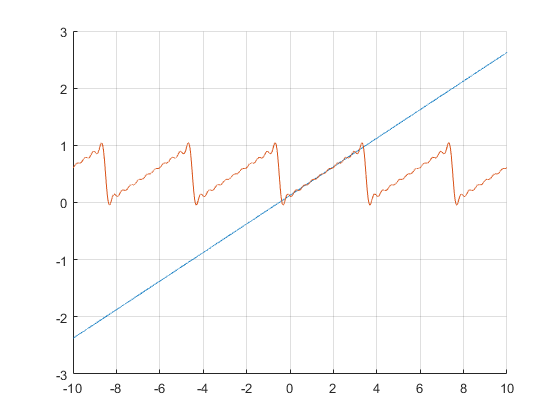

for n = 1:1:N
    A(n) = 1/(2*pi^2*n^2)*(2*pi*n*sin(7*pi*n/4)+cos(7*pi*n/4)-cos(pi*n/4));
    B(n) = 1/(2*pi^2*n^2)*(sin(7*pi*n/4)+sin(pi*n/4)-2*pi*n*cos(7*pi*n/4));
    %B(n) = (1/(2*pi^(2)*n^(2)))*(-(7*pi*n/4)*cos(7*pi*n/4)+sin(7*pi*n/4)-(pi*n/4)*cos(pi*n/4)+sin(pi*n/4))+(1/(8*pi*n))*(cos(pi*n/4)-cos(7*pi*n/4));
    sum = sum + A(n) * cos(2*pi*n/4*x) + B(n) * sin(2*pi*n/4*x);
end
plot(x,sum)
grid on